線形version!!!

初期状態の値(initial_generator_state)と状態定常値の差に関して、定常値に収束するための初期値誤差を調べ、その境界を探索する 

状態における誤差は　10^left　10^right  とおく  ( 例、left = -17 のとき 10^-17 ) 

( left: 最終状態値と状態定常値との差がゼロであるべき指数,  right: 最終状態値と状態定常値との差がゼロではない指数 )

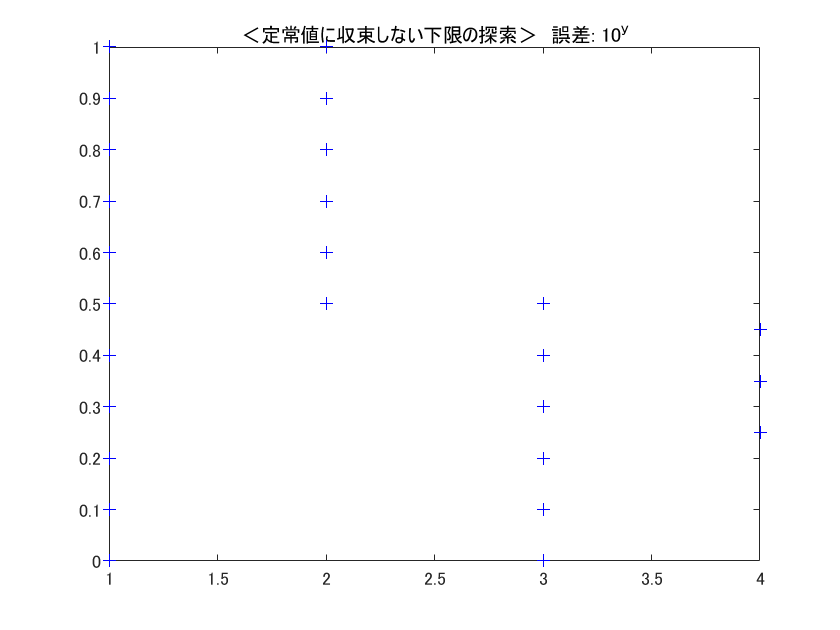

ans = 3

ans =      0     1


ans = 2.0005

error_left =      0     0     0
     0     0     0
     0     0     0


error_right =     1.0000    0.0000    0.0000
    1.0001   -0.0001    0.0000
    0.9999    0.0001    0.0000


ans =     0.5000    1.0000


ans = 1.0001

error_left =     0.5001    0.0000    0.0000
    0.4996   -0.0001    0.0000
    0.5003    0.0000    0.0000


error_right =     1.0000    0.0000    0.0000
    1.0001   -0.0001    0.0000
    0.9999    0.0001    0.0000


ans = 3

ans =          0    0.5000


ans = 1.0001

error_left =      0     0     0
     0     0     0
     0     0     0


error_right =     0.5001    0.0000    0.0000
    0.4996   -0.0001    0.0000
    0.5003    0.0000    0.0000


ans =     0.2500    0.5000


ans = 0.5003

error_left =     0.2502   -0.0000    0.0000
    0.2494    0.0000    0.0000
    0.2504   -0.0000    0.0000


error_right =     0.5001    0.0000    0.0000
    0.4996   -0.0001    0.0000
    0.5003    0.0000    0.0000


clear
left = 1;
right = 2;

tspan = [0 100];

%定常値を設定
steady_delta = [1.1;1.2;1.4];
steady_deltaomega = [0;0;0];
steady_E = [4;5;3];
steady_generator_state = [steady_delta; steady_deltaomega; steady_E];

psi = get_psi(steady_generator_state);

%最終時間における状態値と状態定常値の差を得る
get_final_error_wrap = @(cnt) get_final_error_linear(cnt, tspan, psi);

error_left = get_final_error_wrap(left);
error_right = get_final_error_wrap(right);

t = 1;
f1 = figure;
f2 = figure;

% max(abs(error_right(:))) > ?????　でどれだけの誤差まで許容するかを設定（max(初期値)<1なら0.000001程度、max(初期値)>1なら1）
% t < ???? で最高何回探索するかを設定
while (max(abs(error_right(:))) > 0.00001 || all(error_right(:) == 0) ) && t < 5
    
    if all(error_left(:) == 0) && any(error_right(:) ~= 0)
        
        %1
        if (right - left) < 0.001
            error_left(:)
            4
            break
        end
        
        left = (right + left) /2;
        

        
    elseif  all(error_right(:) == 0)
        
        %2
        
        temp = left;
        
        left = right;
        
        right = right + (right - temp);
        
    elseif any(error_left(:) ~= 0)
        
        if max(abs(error_left(:))) < 0.00001
            break
        end
        
        3
        
        temp = right;
        
        right = left;
        
        left = left - (temp - left);
      
    end
    [left, right]
    max(abs(error_right(:)))
    figure(f1);
    plot(t,left:0.1:right,'b+')
    title('＜定常値に収束しない下限の探索＞　誤差: 10^y')
    hold on
    
    if max(abs(error_right(:))) > 0
        figure(f2);
        plot(t,max(abs(error_right(:))),'r*')
        title('定常値との最大誤差の絶対値')
        hold on
    end
    
    t = t + 1;
    
    error_left = get_final_error_wrap(left)
    error_right = get_final_error_wrap(right)
 
end

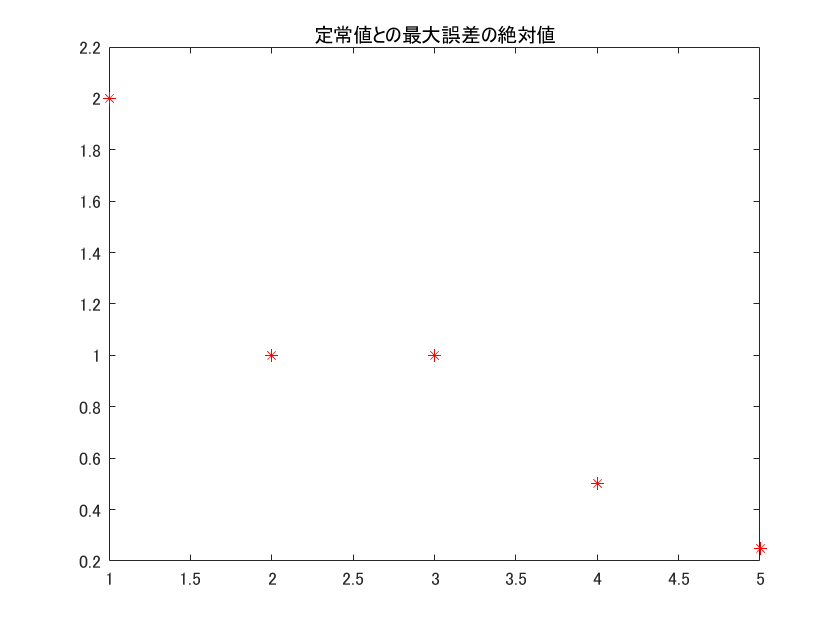

figure(f2);
plot(t,max(abs(error_left(:))),'r*')
hold off

right

right = 0.5000

left

left = 0.2500

figure;
plot_generator_state_linear(right,tspan,psi)

ans = 	1.0e+-4 *

    0.1991   -0.6806    0.4704   -0.0317    0.1161   -0.0781    0.0029   -0.0046   -0.0087


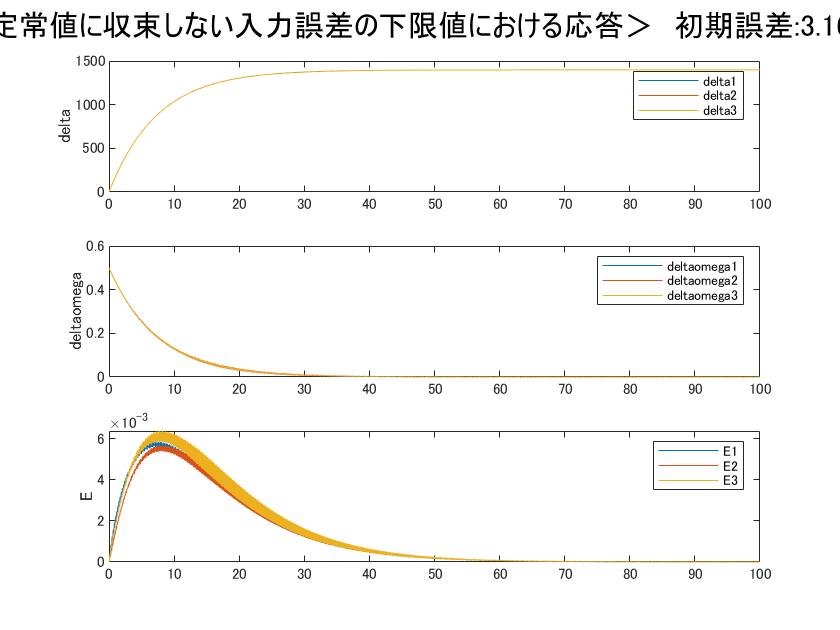

sgtitle(['＜定常値に収束しない入力誤差の下限値における応答＞　初期誤差:',num2str(10^right)])

figure;
plot_generator_state_linear(left,tspan,psi)

ans = 	1.0e+-4 *

   -0.0130    0.0764   -0.0449   -0.0467    0.1705   -0.1146    0.0042   -0.0068   -0.0127


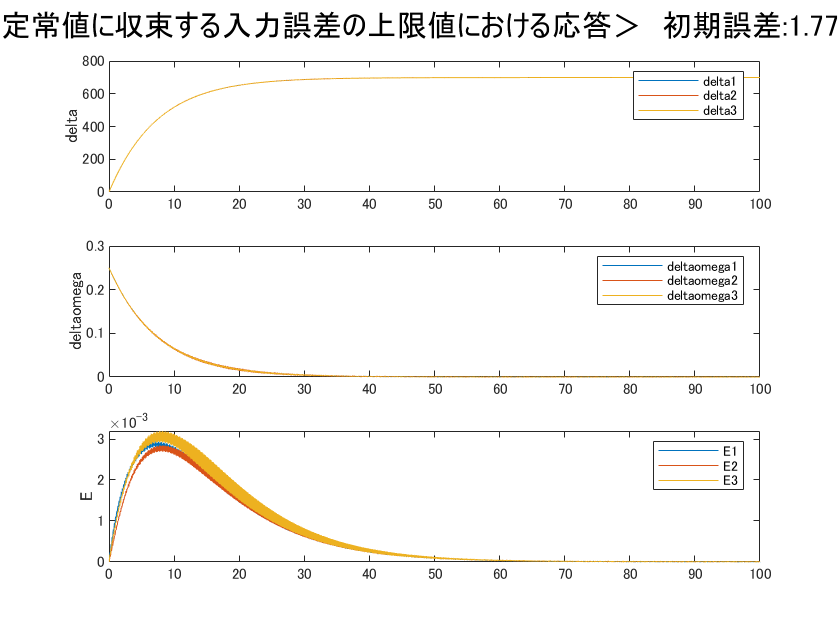

sgtitle(['＜定常値に収束する入力誤差の上限値における応答＞　初期誤差:',num2str(10^left)])